# Gradient Descent and Polynomial Regression

## Order of Polynomial to fit

order = 5;

## Generate a dummy dataset

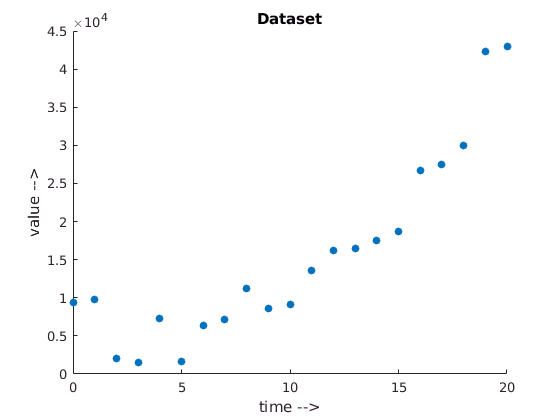

time = 0:20;
value = generateData(time, 10000);
scatter(time, value, 'filled');
title('Dataset');
xlabel('time -->');
ylabel('value -->');

## Normalize the data and create feature vector

x = (time - mean(time)) / std(time);
X = ones(size(x, 2), 2);
for i = 1: order
    X(:, i + 1) = (x') .^ (i);
end
Y = (value - mean(value)) / std(value);

## Gradient Descent

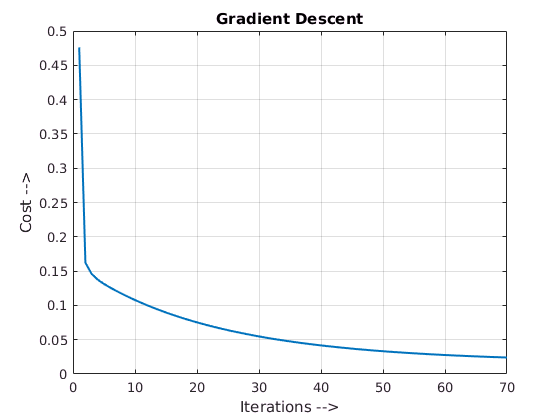

theta = zeros(order + 1, 1);
alpha = 0.05;
num_iter = 70;
m = length(Y);
J = zeros(1, num_iter);
for i = 1: num_iter
    h = hypothesis(X, theta);
    J(1, i) = costf(X, Y, theta);
    for j = 1: order + 1
        theta(j) = theta(j) - alpha * (1/m) * sum((h - Y) .* X(:, j)');
    end
end

plot(1: num_iter, J, 'LineWidth', 1.5);
grid on;
title('Gradient Descent');
xlabel('Iterations -->');
ylabel('Cost -->');

## Result

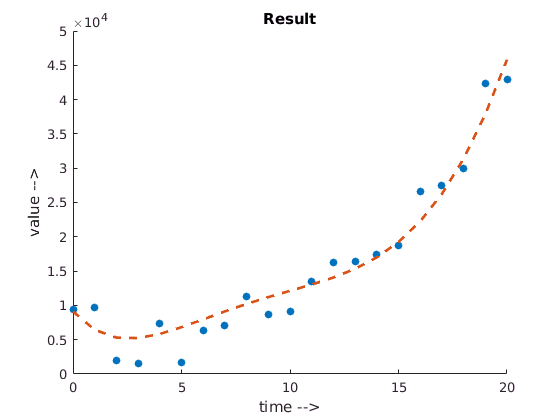

x = (x * std(time)) + mean(time);
Y = (Y * std(value)) + mean(value);
scatter(x, Y, 'filled');
hold on;
y = hypothesis(X, theta);
y = (y * std(value)) + mean(value);
plot(x, y, '--', 'LineWidth', 2); 
title('Result');
xlabel('time -->');
ylabel('value -->');